## 非均匀数据

• 并非所有数据都由等间距的点组成，这可能会影响数据处理的方法。

• 包含 `Airreg`数据的不规则采样时间的日期时间向量。

• 时间向量表示前30分钟每分钟采样一次，随后两天内每小时采样一次。

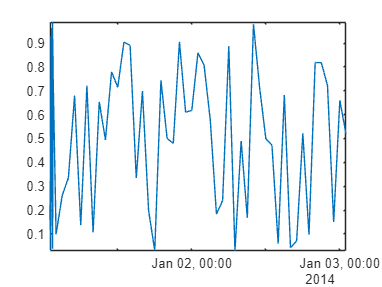

t0 = datetime(2014,1,1,1,1,1);
timeminutes = sort(t0 + minutes(1:30));
timehours = t0 + hours(1:48);
time = [timeminutes timehours];
Airreg = rand(1,length(time));
plot(time,Airreg)
axis tight

**如果我们仍然相对于等间距的整数进行平滑处理**

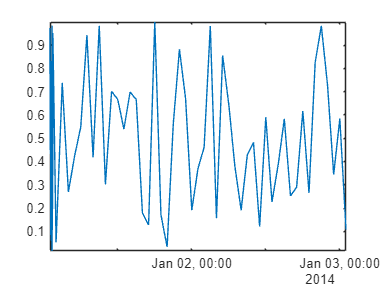

t0 = datetime(2014,1,1,1,1,1);
timeminutes = sort(t0 + minutes(1:30));
timehours = t0 + hours(1:48);
time = [timeminutes timehours];
Airreg = rand(1,length(time));
plot(time,Airreg)
axis tight

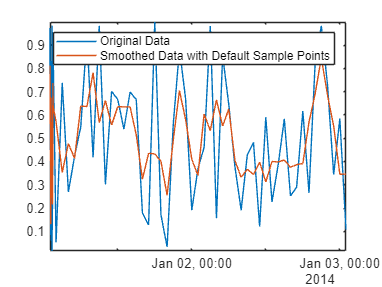


Adefault = smoothdata(Airreg,'movmean',3);
plot(time,Airreg,time,Adefault)
axis tight
legend('Original Data','Smoothed Data with Default Sample Points')

为了去除数据前半小时的高频变化，请将时间戳与 `'SamplePoints'`选项一起使用。

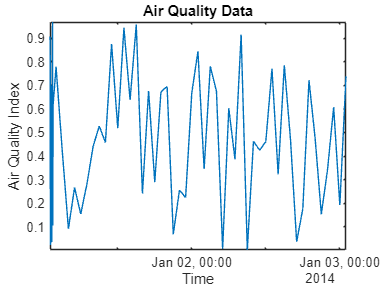

t0 = datetime(2014,1,1,1,1,1);
timeminutes = sort(t0 + minutes(1:30)); % 生成分钟时间戳
timehours = t0 + hours(1:48); % 生成小时时间戳
time = [timeminutes timehours]; % 合并两个时间向量
Airreg = rand(1,length(time)); % 生成随机数据

% 检查 Airreg 中的 NaN 值
if any(isnan(Airreg))
    disp('警告: Airreg 包含 NaN 值。');
end

% 绘制原始数据
figure; % 创建新图形
plot(time, Airreg);
axis tight;
title('Air Quality Data');
xlabel('Time');
ylabel('Air Quality Index');

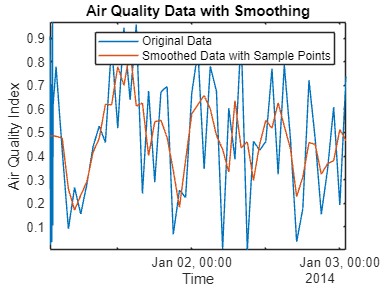


% 平滑数据
Asamplepoints = smoothdata(Airreg, 'movmean', hours(3), 'omitnan', 'SamplePoints', time);
% 绘制原始数据和平滑后的数据
figure; % 创建新图形
plot(time, Airreg, time, Asamplepoints);
axis tight;
title('Air Quality Data with Smoothing');
xlabel('Time');
ylabel('Air Quality Index');
legend('Original Data', 'Smoothed Data with Sample Points');